# Mars Rover: Final Project

Follow the instructions provided in the course to complete your final project. 

### Load the images

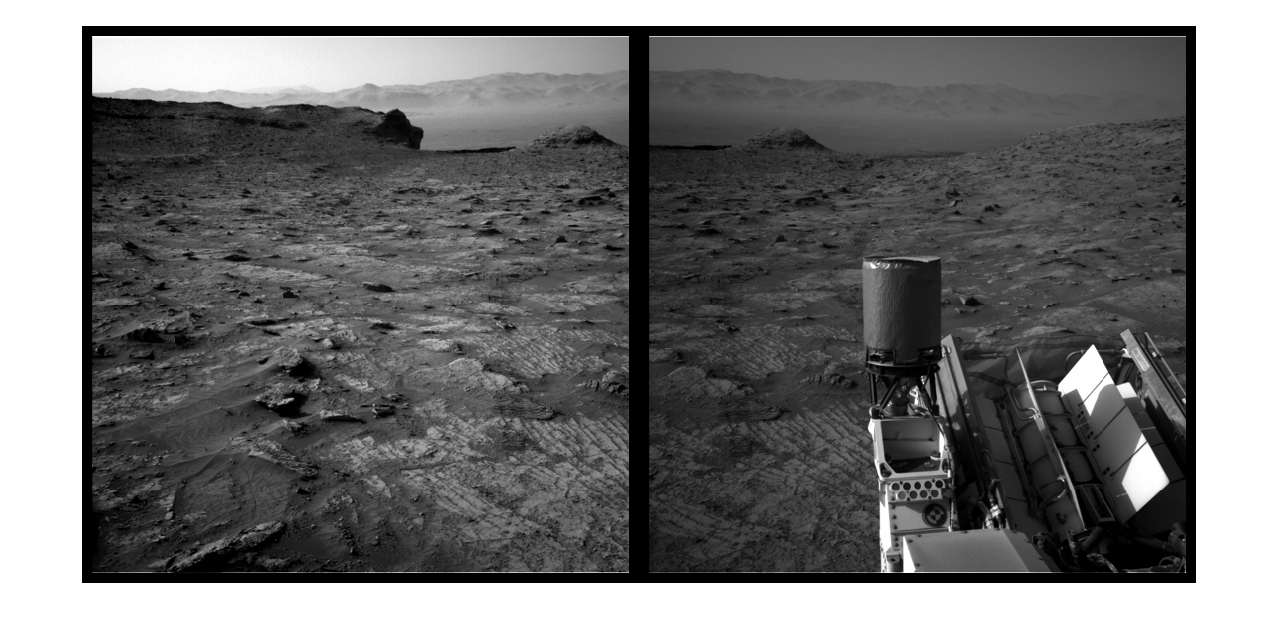

fixedImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");

montage({movingImg, fixedImg},"BorderSize",[10 10])

### Register the Images

Use the Registration Estimator app to create a function that registers the images. Then, use that function to return the registration structure.

When you're happy with your registration function, return to the course and use the online grader to check if it gives the correct result.

regOutput = RegisterImages(fixedImg, movingImg)

regOutput = struct with fields:
     FixedMatchedFeatures: [191×1 SURFPoints]
    MovingMatchedFeatures: [191×1 SURFPoints]
           Transformation: [1×1 projective2d]
          RegisteredImage: [1024×1024 uint8]
            SpatialRefObj: [1×1 imref2d]


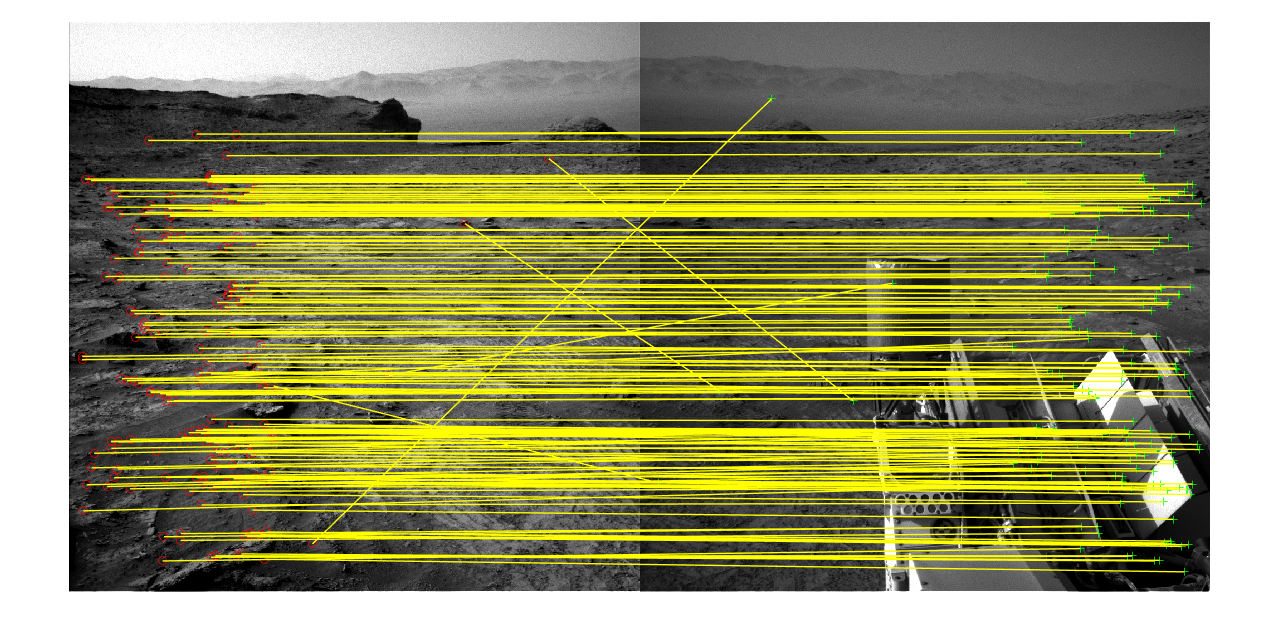

figure;
showMatchedFeatures(movingImg, fixedImg, regOutput.MovingMatchedFeatures, regOutput.FixedMatchedFeatures, "montage")

tform = regOutput.Transformation;

### Initialize the Panorama

Use your geometric transformation to determine the world coordinates and initialize an empty panorama image. Here, recall that you're working with **grayscale** images, unlike the color concrete images.

When you're done, return to the course and take the quiz to check if your panorama dimensions are as expected.

tformInv = invert(tform);

imageSize = size(fixedImg); 
xLimitsRef = [1 imageSize(2)];
yLimitsRef = [1 imageSize(1)];
[xLimitsWarp, yLimitsWarp] = outputLimits(tformInv, [1 size(movingImg,2)], [1 size(movingImg,1)]);


xMin = min([xLimitsRef(1), xLimitsWarp(1)]);
xMax = max([xLimitsRef(2), xLimitsWarp(2)]);
yMin = min([yLimitsRef(1), yLimitsWarp(1)]);
yMax = max([yLimitsRef(2), yLimitsWarp(2)]);
widthPanorama  = round(xMax - xMin);
heightPanorama = round(yMax - yMin);
panoramaRef = imref2d([heightPanorama widthPanorama], [xMin xMax], [yMin yMax]);
panorama = zeros([heightPanorama widthPanorama size(fixedImg,3)], 'like', fixedImg);

### Create the Panorama

Use the `vision.AlphaBlender `object to create the final panorama. When you're done, pass your final image to the `testMarsImage` function to see if it's correct. 

If you're correct, go back to the quiz and add the numeric code to complete the course!

If you get a dimension error while using `AlphaBlender`, double check that you are initializing the empty panorama correctly for a grayscale image. Remember that the third dimension of a color image has size 3, but the third dimension of a grayscale image only has size 1.

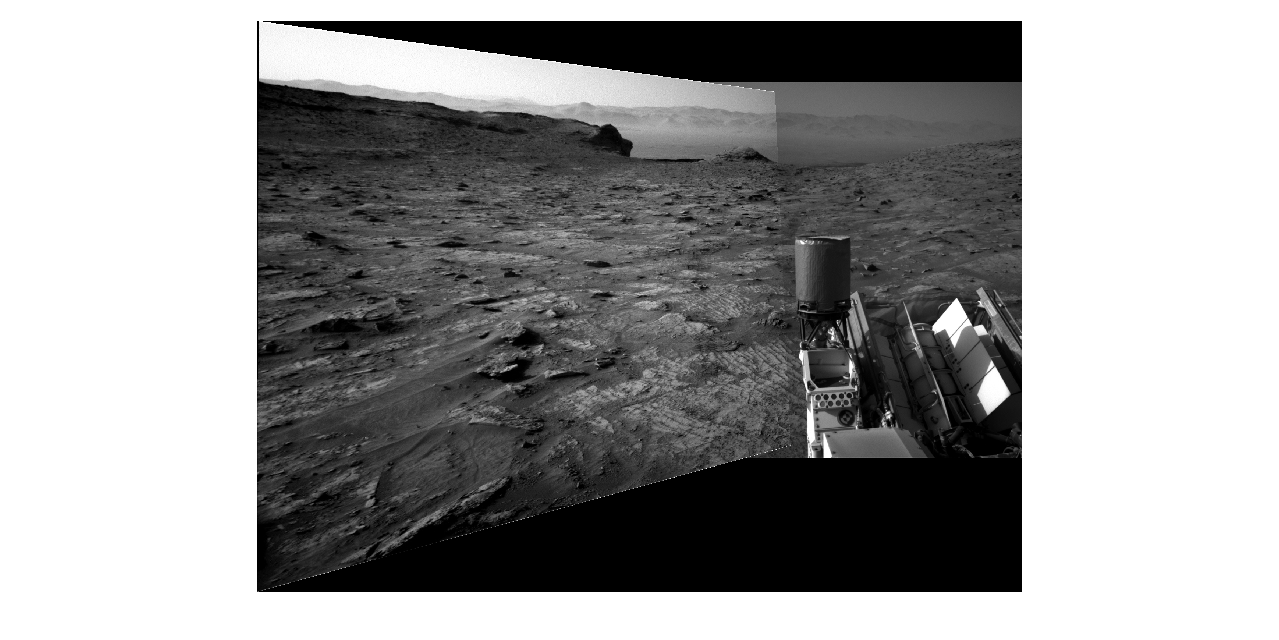


warpedMoving = imwarp(movingImg, tformInv, 'OutputView', panoramaRef);
maskMoving = imwarp(true(size(movingImg,1), size(movingImg,2)), tformInv, 'OutputView', panoramaRef);
warpedFixed = imwarp(fixedImg, affine2d(eye(3)), 'OutputView', panoramaRef);
maskFixed = imwarp(true(size(fixedImg,1), size(fixedImg,2)), affine2d(eye(3)), 'OutputView', panoramaRef);

blender = vision.AlphaBlender('Operation', 'Binary mask', 'MaskSource', 'Input port');
panorama = step(blender, panorama, warpedFixed, maskFixed);
panorama = step(blender, panorama, warpedMoving, maskMoving);

imshow(panorama)

*Copyright 2022 The MathWorks, Inc.*